# Guía 2 - Ejercicio 5

## Enunciado

Encontrar un perceptrón multicapa que resuelva una XOR de 2 entradas mediante simulated annealing.

clear all
close all
Capa1 = 4;
w_0 = normrnd(0,0.1,[Capa1 2]);%(rand([2 2])-0.5)*chico;
bias_0 = normrnd(0,0.1,[1 Capa1]);%(rand([1 2])-0.5)*chico;
w_1 = normrnd(0,0.1,[Capa1 1]);%(rand([2 1])-0.5)*chico;
bias_1 = normrnd(0,0.1,[1 1]);%(rand([1 1])-0.5)*chico;
x = [-1 -1;...
     -1  1;...
      1 -1;...
      1  1];
errores = [];
T=0.1;
alfa = 0.999;
error_acumulado=inf;


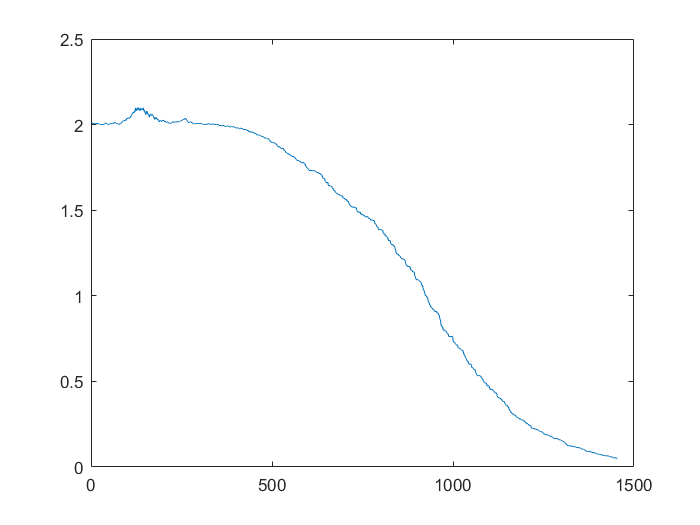

%FORWARD
while error_acumulado>0.05%for j=1:10000
  orden_aleatorio = randperm(4);
  error_acumulado=0;
  error_acumulado2=0;
  for i=1:4
      alguno=orden_aleatorio(i);
      entrada = x(alguno,:);
      V1 = tanh(entrada*w_0'+bias_0);
      salida = tanh(V1*w_1+bias_1);
      if entrada(1) ~= entrada(2)
          y_deseado = 1;
      else
          y_deseado=-1;
      end 
      error = 0.5*(salida-y_deseado)^2;
      error_acumulado = error_acumulado + error;
  end
  
  
      Deltabias1 = normrnd(0,0.01,[1 1]);
      Deltaw1 = normrnd(0,0.01,[Capa1 1]);
      Deltabias0 = normrnd(0,0.01,[1 Capa1]);
      Deltaw0 = normrnd(0,0.01,[Capa1 2]);
      
      %vector_total = [Deltabias0(:)' Deltabias1(:)' Deltaw0(:)' Deltaw1(:)'];
      %norma = norm(vector_total)*10;
      norma=1;
      Deltabias1 = Deltabias1/norma;
      Deltaw1 = Deltaw1/norma;
      Deltabias0 = Deltabias0/norma;
      Deltaw0 = Deltaw0/norma;
      
      %UPDATE
      w_0 = w_0+Deltaw0;
      bias_0 = bias_0+Deltabias0;
      w_1 = w_1+Deltaw1;
      bias_1 = bias_1+Deltabias1;
  for i=1:4   
      %CHANGE
      alguno=orden_aleatorio(i);
      entrada = x(alguno,:);
      V1 = tanh(entrada*w_0'+bias_0);
      salida2 = tanh(V1*w_1+bias_1);
      if entrada(1) ~= entrada(2)
          y_deseado = 1;
      else
          y_deseado=-1;
      end 
      error2 = 0.5*(salida2-y_deseado)^2;
      error_acumulado2 = error_acumulado2 + error2;
  end
  
      if error_acumulado2<error_acumulado

      elseif rand(1)<exp((error_acumulado-error_acumulado2)/(T))

      else
          w_0 = w_0-Deltaw0;
          bias_0 = bias_0-Deltabias0;
          w_1 = w_1-Deltaw1;
          bias_1 = bias_1-Deltabias1;
      end
      T = alfa*T;
  
  errores = [errores error_acumulado];
end
plot(errores)

entrada = [1 -1]

entrada =      1    -1


V1 = tanh(entrada*w_0'+bias_0);
salida = tanh(V1*w_1+bias_1)

salida = 0.8685

T

T = 4.5037e-08